## Synthesis of Robust and stable controler from Desired response 

## Initizilation

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);



## Filter

s=tf('s');
%Wz
WZ = 1/10000000*eye(4)*(1)/(s+1);
param = model.calculateWz(param,WZ,1);
% figure()
% bode(WZ)
%Ww
WW = 1/(2*pi)*eye(4)*s/(1/(2*pi)*s+1);
param = model.calculateWw(param,WW,1);

%Wref
% 
wref =eye(4)*(1/(20*s+1))

wref =
 
  From input 1 to output...
          1
   1:  --------
       20 s + 1
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
          1
   2:  --------
       20 s + 1
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
          1
   3:  --------
       20 s + 1
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
          1
   4:  --------
       20 s + 1
 
Continuous-time transfer function.


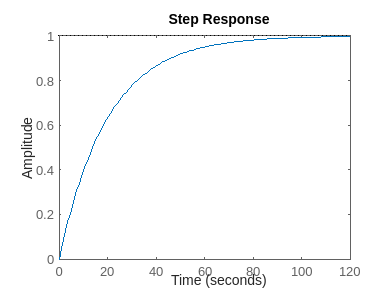

wrefSS = ss(wref);
param.model.AWref = wrefSS.A; 
param.model.BWref = wrefSS.B;
param.model.CWref = wrefSS.C;
param.model.DWref = wrefSS.D;
figure()
step(wref(1,1))

% 
% param.model.AWref = zeros(4);%zeros(4); 
% param.model.BWref = zeros(4);
% param.model.CWref = zeros(4);
% param.model.DWref = diag([1,1,1,1]);
% wref = ss(param.model.AWref,param.model.BWref,param.model.CWref,param.model.DWref)

%Wu 
param.model.AWu = zeros(4); 
param.model.BWu = zeros(4);
param.model.CWu = zeros(4);
param.model.DWu = 0*eye(4);


## Control

param = control.DesignProcedureRobustPerformanceAndRobustStabilityWeighted(param,1); 

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0343
       solvertime: 0.1910
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|           0.53616|      1.7412e-10|
|   #2|        Matrix inequality|           0.25806|      5.4921e-12|
|   #3|        Matrix inequality|        -4.901e-17|      1.8703e-10|
|   #4|   Elementwise inequality|           0.23045|      3.0337e-08|
|   #5|        Matrix inequality|        4.4725e-06|      6.8852e-12|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals. |
| In practice, many solvers converge to slightly infeasible         |
| solutions, which may cause some residuals to be negative.         |
| It is up to the user to judge the importance and impact of        |
| slightly negative residuals (i.e. infeasibilities)                |
| https://yalmip.g

ans = NaN

gamma desired per


ans = 0.2305

gamma robust stab


ans = NaN

k =     6.4042   -1.1463    0.1497         0         0         0         0         0         0         0         0         0
         0         0         0    4.9362   -1.2010    0.0744         0         0         0         0         0         0
         0         0         0         0         0         0    3.7592   -1.1019    0.0232         0         0         0
         0         0         0         0         0         0         0         0         0    4.1531   -1.0968    0.0412


Eig of Q_hat


ans = 1.0e+03 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0012
    0.0012
    0.0013
    0.0013
    0.0072
    0.0099


## Verify robust stability

By calculating Mw and taking the Hinfnorm the robust stability can be verified 

Mw = model.calculateMw(param);

s =
 
  s
 
Continuous-time transfer function.
Model Properties


hinfnorm(Mw)

ans = 0.2282

### Calculate Nper

This is used to understand how the weights shape the bode plot and thereby the performance

Cz = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
Dz = eye(4);

A_hat = [param.model.A, Bw*param.model.Cww, zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,12),param.model.Aww, zeros(4),zeros(4),zeros(4);
         param.model.Bwz*Cz, -param.model.Bwz*param.model.DWref*param.model.Cww, param.model.Awz, -param.model.Bwz*param.model.CWref,zeros(4);
         zeros(4,12),param.model.BWref*param.model.Cww, zeros(4),param.model.AWref,zeros(4);
         zeros(4,12), zeros(4),zeros(4),zeros(4),param.model.AWu]; 

B_hat = [param.model.B, zeros(12,4),zeros(12,4),zeros(12,4),zeros(12,4);
         zeros(4,20);
         zeros(4,20);
         zeros(4,20);
         param.model.BWu,zeros(4,16)];

B_bar = [Bw*param.model.Dww, param.model.B;
         param.model.Bww, zeros(4);
         -param.model.Bwz*param.model.DWref*param.model.Dww, zeros(4);
         param.model.BWref*param.model.Dww,zeros(4);
         zeros(4,8)];

C1 = [param.model.Dwz*Cz, -param.model.Dwz*param.model.DWref*param.model.Cww, param.model.Cwz,-param.model.Dwz*param.model.CWref,zeros(4);
      zeros(4,12),zeros(4),zeros(4),zeros(4),param.model.CWu;
      zeros(4,28)];


C2 = [zeros(4,20);
      param.model.DWu,zeros(4,16);
      param.model.Dwd, zeros(4,16)];

D_Bar = [-param.model.Dwz*param.model.DWref*param.model.Dww,zeros(4);
        zeros(4,8);
        zeros(4,8)];


param.model.AWref = zeros(4);%zeros(4); 
param.model.BWref = zeros(4);
param.model.CWref = zeros(4);
param.model.DWref = zeros(4); %diag([1,1,1,1]);
% 

K_hat = blkdiag(param.ctrl.K*param.model.Cy,eye(4),eye(4),eye(4),eye(4));
N = (C1+C2*K_hat)/(s*eye(28)-(A_hat+B_hat*K_hat))*B_bar+D_Bar;

## Simulate The nonlinear system

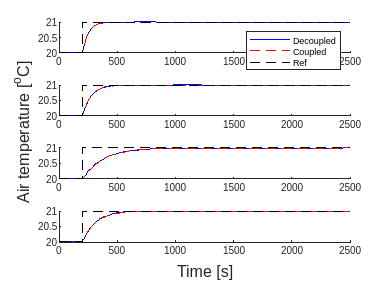

 util.SimulateStep(param,"TestPerAndStab",0);

## Obtain Ww and Wz 

- Simulate the system with feedforward Ww and Wz, determine the performance. Too aggresisve (overshoot).  Design Ww to be more costly for the current bandwith to affect the system.

-    WZ = 1/200*eye(4)*(s+20)/(s+1) 

-     WW = 1; 

-     fint respons 

- prøv med WW 

- WZ = 1 